# 水印嵌入位置分析

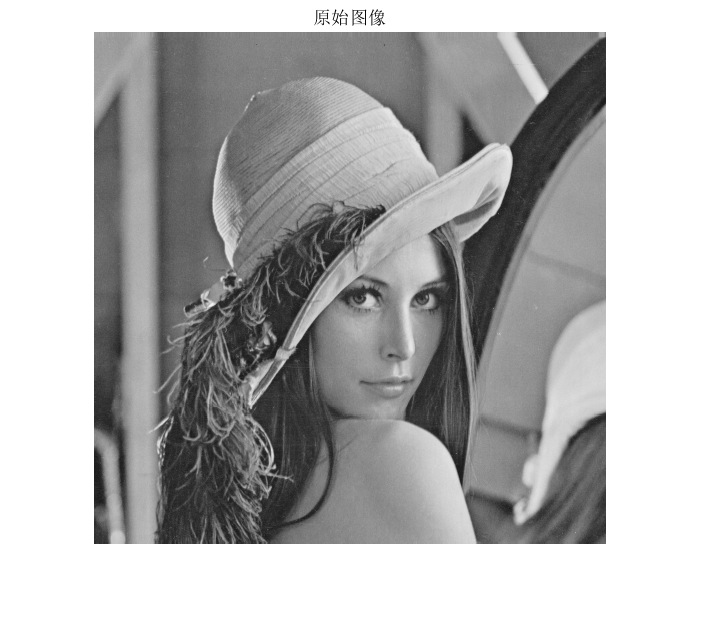

% 对Lena图像不同的位平面进行水印嵌入，分析嵌入水印后图像的峰值信噪比
% Lena图像：512x512 灰度图
% 水印图像：64x64 二值图像
I = imread('in/lena.bmp');
w = imread('in/sdust.bmp');
imshow(I); title('原始图像')

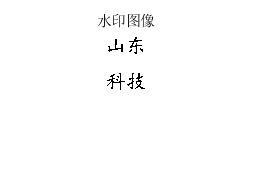

imshow(w); title('水印图像');

% 转换为0-1
w = w / 255;

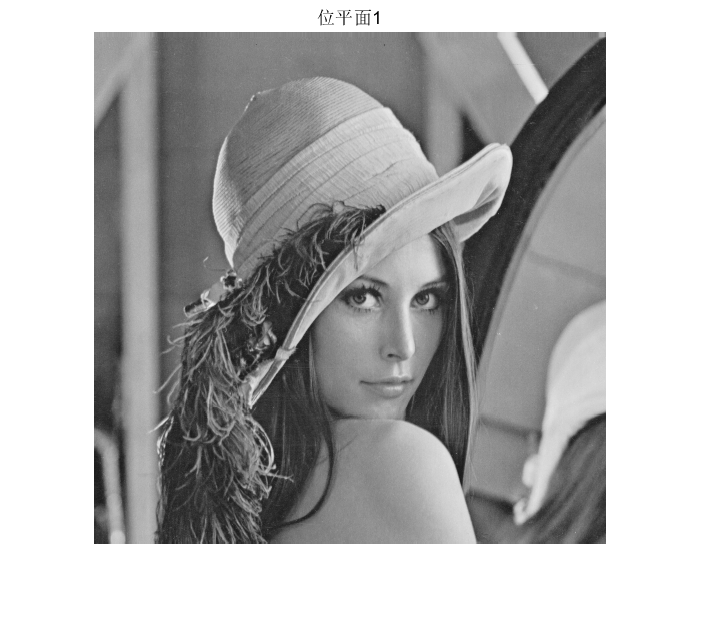

% 位平面1
J1 = embedded(I, w, 1);
imshow(J1); title('位平面1');

fprintf('PSNR: %f\n', psnr(I, J1));

PSNR: 69.196546


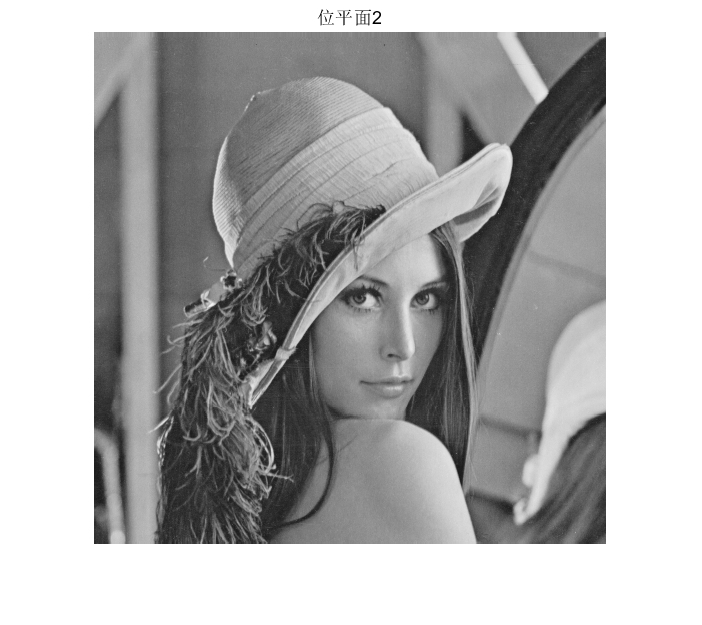

% 位平面2
J2 = embedded(I, w, 2);
imshow(J2); title('位平面2');

fprintf('PSNR: %f\n', psnr(I, J2));

PSNR: 63.144300


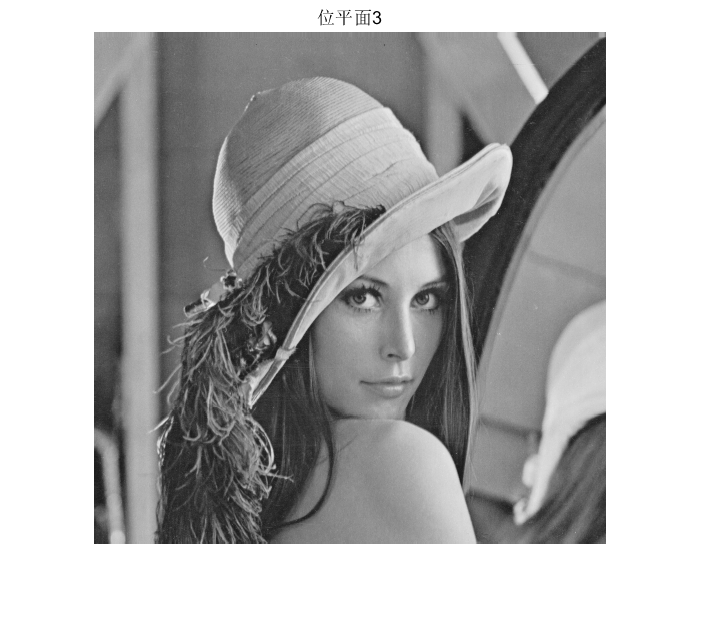

% 位平面3
J3 = embedded(I, w, 3);
imshow(J3); title('位平面3');

fprintf('PSNR: %f\n', psnr(I, J3));

PSNR: 57.106915


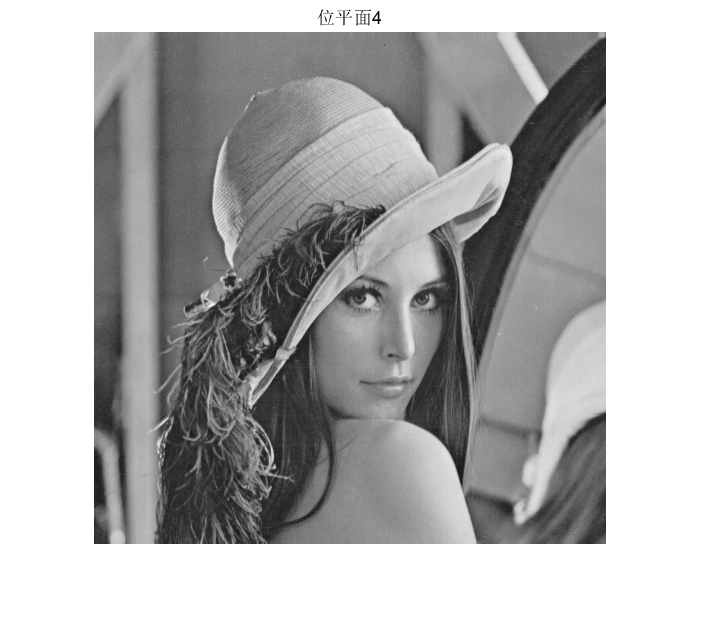

% 位平面4
J4 = embedded(I, w, 4);
imshow(J4); title('位平面4');

fprintf('PSNR: %f\n', psnr(I, J4));

PSNR: 51.026010


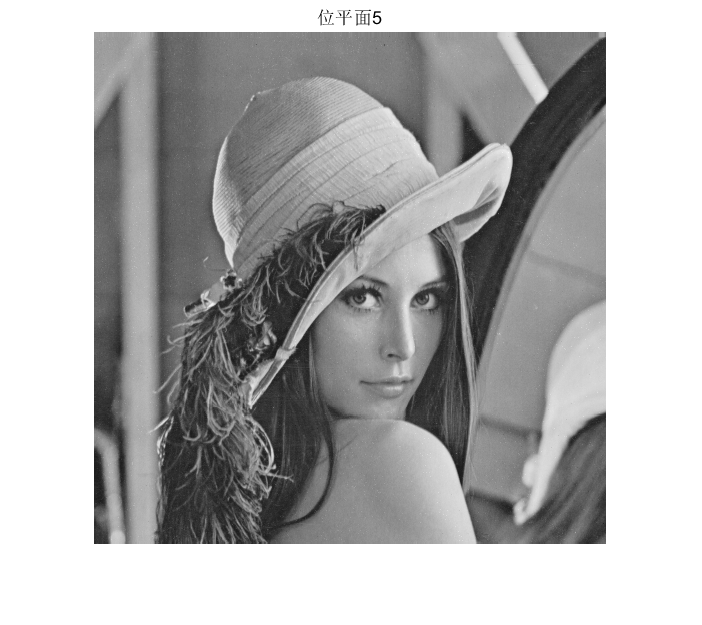

% 位平面5
J5 = embedded(I, w, 5);
imshow(J5); title('位平面5');

fprintf('PSNR: %f\n', psnr(I, J5));

PSNR: 45.086706


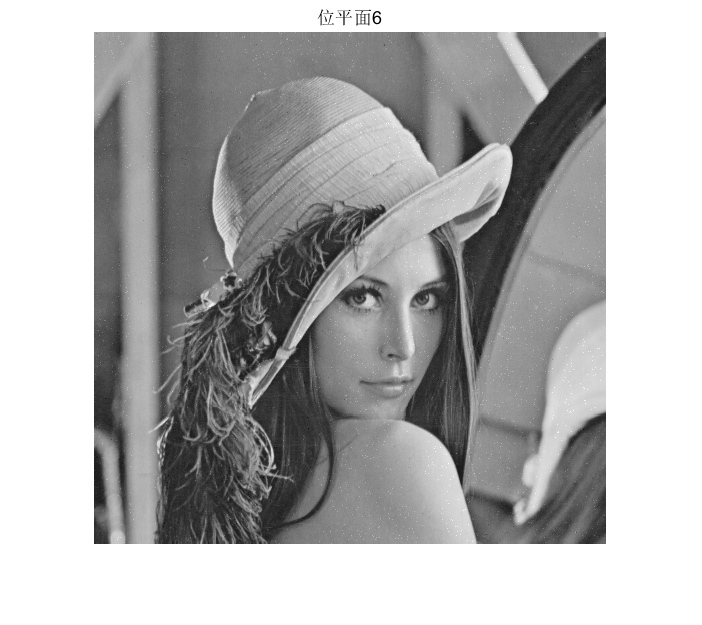

% 位平面6
J6 = embedded(I, w, 6);
imshow(J6); title('位平面6');

fprintf('PSNR: %f\n', psnr(I, J6));

PSNR: 39.131829


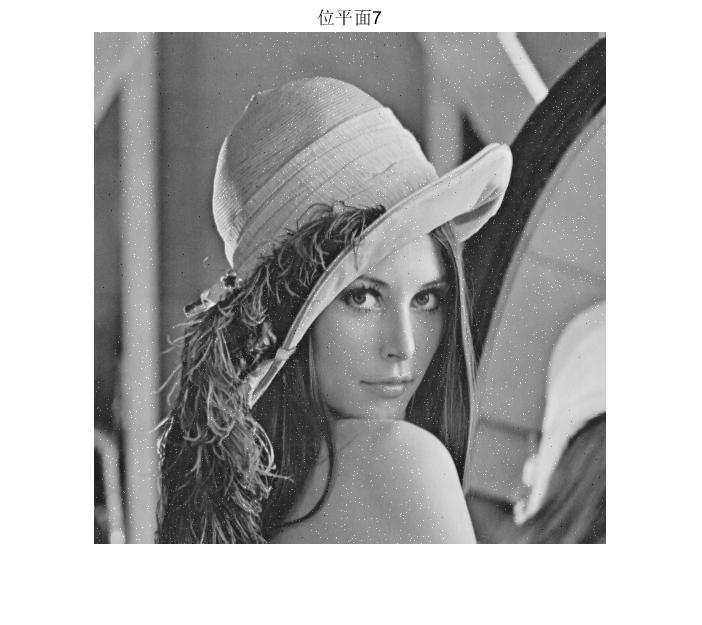

% 位平面7
J7 = embedded(I, w, 7);
imshow(J7); title('位平面7');

fprintf('PSNR: %f\n', psnr(I, J7));

PSNR: 32.423186


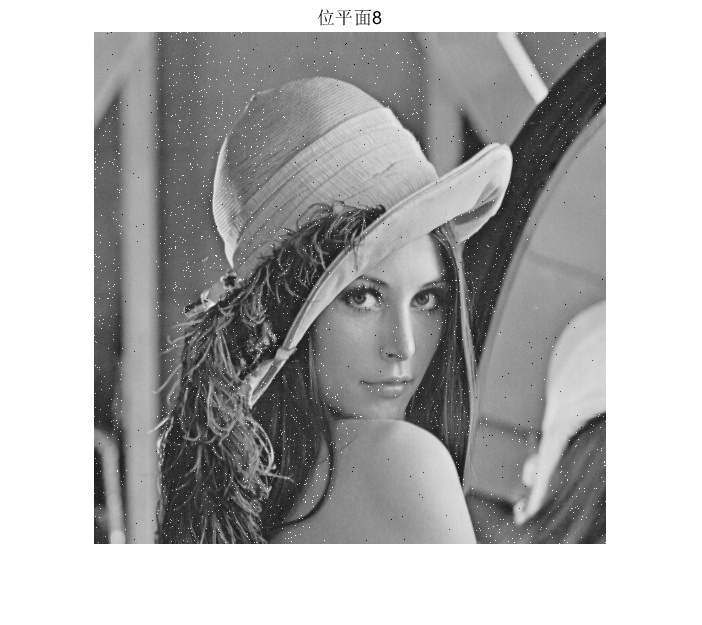

% 位平面8
J8 = embedded(I, w, 8);
imshow(J8); title('位平面8');

fprintf('PSNR: %f\n', psnr(I, J8));

PSNR: 27.079962


function result = embedded(img, w, pos)
    result = img;
    [m1, n1] = size(img);
    [m2, n2] = size(w);
    i = randperm(m1 * n1, m2 * n2);
    for j = 1:m2*n2
        result(i(j)) = bitset(img(i(j)), pos, w(j));
    end
end